## Final Project!!

clear
%import data 
Factors = table2struct(readtable('riskfactors.csv'));

% extract country code from the data set into a cell
% Factors.Country = categorical({Factors.Country});
countryNames = {Factors.Code};
% extract country code from the data set into a cell
countryCodes = {Factors.Code};




## Graphing based on user input

[vecnum, y] = size(Factors);
% ask user for country code
inputCode = input('Enter country code: ','s');

% extract a list of indeces where the data has the entered country code
listout = [];
for i = 1:vecnum
    if isequal({inputCode}, countryCodes(i))
        listout = [listout, i];      
    end
end
% disp(listout)


## Actual Graphing Part

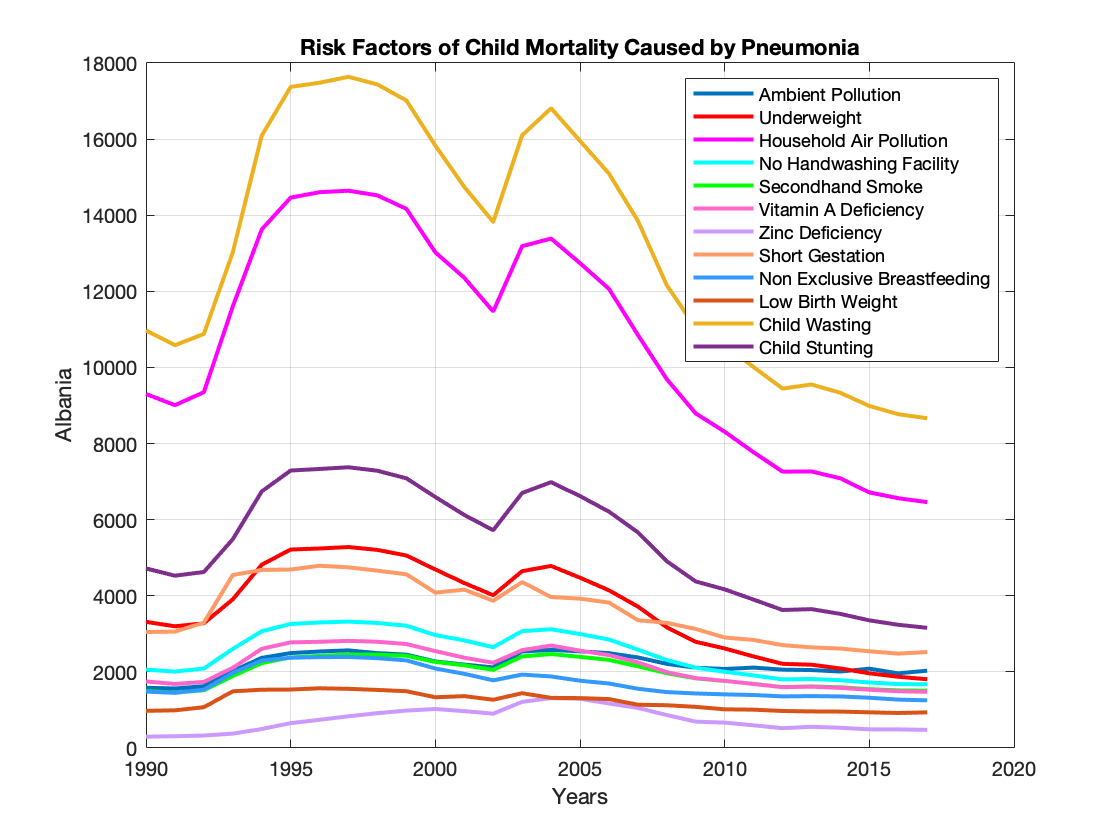

figure(1)
% initialize two empty lists to later store x y values of user's choice
x = zeros(1, length(listout));
yGraphAP = zeros(1, length(listout));
yGraphUW = zeros(1, length(listout));
yGraphHAP = zeros(1, length(listout));
yGraphHWF = zeros(1, length(listout));
yGraphSHS = zeros(1, length(listout));
yGraphVAD = zeros(1, length(listout));
yGraphZD = zeros(1, length(listout));
yGraphSG = zeros(1, length(listout));
yGraphNBF = zeros(1, length(listout));
yGraphLBW = zeros(1, length(listout));
yGraphCW = zeros(1, length(listout));
yGraphCT = zeros(1, length(listout));

% extract years and different factors of the given indicies
for i = 1:length(listout)
    x(i) = [Factors(i).Year];
    % different factors
    yGraphAP(i) = [Factors(i).AmbientPollution];
    yGraphUW(i) = [Factors(i).Underweight];
    yGraphHAP(i) = [Factors(i).HouseholdAirPollution];
    yGraphHWF(i) = [Factors(i).NoHandwashingFacility];
    yGraphSHS(i) = [Factors(i).SecondhandSmoke];
    yGraphVAD(i) = [Factors(i).VitaminADeficiency];
    yGraphZD(i) = [Factors(i).ZincDeficiency];
    yGraphSG(i) = [Factors(i).ShortGestation];
    yGraphNBF(i) = [Factors(i).Non_exclusiveBreastfeeding];
    yGraphLBW(i) = [Factors(i).LowBirthWeight];
    yGraphCW(i) = [Factors(i).ChildWasting];
    yGraphCT(i) = [Factors(i).ChildStunting];
end

% disp(x)
% disp(yGraph)
g = plot(x, yGraphAP, 'Color', [0, 0.4470, 0.7410]);
g(1).LineWidth = 2;
hold on
g = plot(x, yGraphUW, 'r-');
g(1).LineWidth = 2;
g = plot(x, yGraphHAP, 'm-');
g(1).LineWidth = 2;
g = plot(x, yGraphHWF, 'c-');
g(1).LineWidth = 2;
g = plot(x, yGraphSHS, 'g-');
g(1).LineWidth = 2;
g = plot(x, yGraphVAD, 'Color', [1.0 0.4 0.8]);
g(1).LineWidth = 2;
g = plot(x, yGraphZD, 'Color', [0.8 0.6 1.0]);
g(1).LineWidth = 2;
g = plot(x, yGraphSG, 'Color', [1.0 0.6 0.4]);
g(1).LineWidth = 2;
g = plot(x, yGraphNBF, 'Color', [0.2 0.6 1.0]);
g(1).LineWidth = 2;
g = plot(x, yGraphLBW, 'Color', [0.8500, 0.3250, 0.0980]);
g(1).LineWidth = 2;
g = plot(x, yGraphCW, 'Color', [0.9290, 0.6940, 0.1250]);
g(1).LineWidth = 2;
g = plot(x, yGraphCT, 'Color', [0.4940, 0.1840, 0.5560]);
g(1).LineWidth = 2;

grid on
xlabel('Years');
ylabl = Factors(listout(1)).Country;
ylabel(ylabl);

title('Risk Factors of Child Mortality Caused by Pneumonia');
legend('Ambient Pollution', 'Underweight', 'Household Air Pollution', ...
    'No Handwashing Facility', 'Secondhand Smoke', 'Vitamin A Deficiency', ...
    'Zinc Deficiency', 'Short Gestation', 'Non Exclusive Breastfeeding',...
    'Low Birth Weight', 'Child Wasting', 'Child Stunting');
hold off

## Prediction